clear
Slist = [[0; 0; 1;   0; 0; 0], ...
    [0; 1; 0;   -.089;   0;   0], ...
    [0; 1; 0;   -.089;   0;   .425], ...
    [0; 1; 0; -.089; 0; .817], ...
    [0; 0; -1;   -.109;   .817;   0], ...
    [0; 1; 0;   .006;   0;   .817]]

Slist =          0         0         0         0         0         0
         0    1.0000    1.0000    1.0000         0    1.0000
    1.0000         0         0         0   -1.0000         0
         0   -0.0890   -0.0890   -0.0890   -0.1090    0.0060
         0         0         0         0    0.8170         0
         0         0    0.4250    0.8170         0    0.8170


theta = [pi/2; pi/2;pi/2;pi/2;pi/2;pi/2;]

theta =     1.5708
    1.5708
    1.5708
    1.5708
    1.5708
    1.5708


Js = JacobianSpace(Slist, theta)

Js =          0   -1.0000   -1.0000   -1.0000    0.0000   -0.0000
         0    0.0000    0.0000    0.0000    1.0000   -0.0000
    1.0000         0         0         0    0.0000    1.0000
         0   -0.0000    0.0000    0.0000    0.3360   -0.2970
         0   -0.0890    0.3360    0.3360   -0.0000    0.1090
         0         0    0.0000   -0.3920   -0.1090    0.0000


% angular velocity
Jw = Js(1:3,:)

Jw =          0   -1.0000   -1.0000   -1.0000    0.0000   -0.0000
         0    0.0000    0.0000    0.0000    1.0000   -0.0000
    1.0000         0         0         0    0.0000    1.0000


Aw =Jw*Jw'

Aw =     3.0000   -0.0000   -0.0000
   -0.0000    1.0000         0
   -0.0000         0    2.0000


[W_vec, W_val] = eig(Aw)

W_vec =      0     0     1
     1     0     0
     0     1     0


W_val =     1.0000         0         0
         0    2.0000         0
         0         0    3.0000


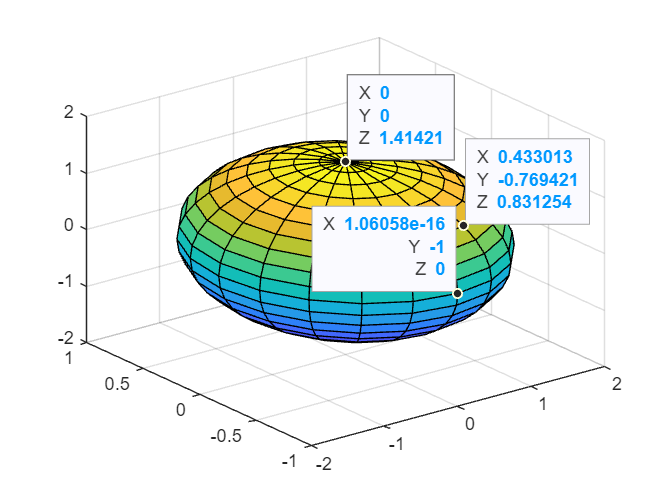

% angular ellipsoid:
[X,Y,Z] = ellipsoid(0,0,0,sqrt(W_val(3,3)),sqrt(W_val(1,1)),sqrt(W_val(2,2)));
S = surf(X,Y,Z);
datatip(S,1.732,0,0); % x-semi-axis: 1.73
datatip(S,0,-1,0);    % y-semi-axis: 1
datatip(S,0,0,1.414); % z-semi-axis: 1.41



%linear velocity
Jv = Js(4:6,:)

Jv =          0   -0.0000    0.0000    0.0000    0.3360   -0.2970
         0   -0.0890    0.3360    0.3360   -0.0000    0.1090
         0         0    0.0000   -0.3920   -0.1090    0.0000


Av = Jv*Jv'

Av =     0.2011   -0.0324   -0.0366
   -0.0324    0.2456   -0.1317
   -0.0366   -0.1317    0.1655


[V_vec, V_val] = eig(Av)

V_vec =     0.3106    0.9500   -0.0314
    0.5696   -0.1596    0.8062
    0.7609   -0.2683   -0.5907


V_val =     0.0520         0         0
         0    0.2169         0
         0         0    0.3434


%v_vec is a rotation matrix
Theta_V = acos(.5*(trace(V_vec)-1))

Theta_V = 2.3744

Theta_V_deg= rad2deg(Theta_V)

Theta_V_deg = 136.0441

Omega_V_skew = 1/(2*sin(Theta_V))*(V_vec-V_vec')

Omega_V_skew =          0    0.2740   -0.5708
   -0.2740         0    0.7740
    0.5708   -0.7740         0


Omega_V= so3ToVec(Omega_V_skew)

Omega_V =    -0.7740
   -0.5708
   -0.2740


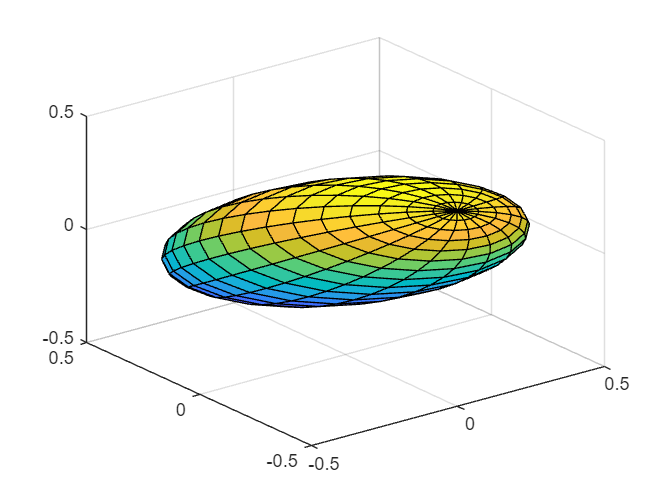

% linear ellipsoid:
[X,Y,Z] = ellipsoid(0,0,0,sqrt(V_val(1,1)),sqrt(V_val(2,2)),sqrt(V_val(3,3)));
S = surf(X,Y,Z);
rotate(S,Omega_V,Theta_V_deg);


%force ellipsoids
Jit= inv(Js')

Jit =    -0.0000   -0.7906   -0.2094   -0.0000    0.0000    0.0000
   -1.1313    0.2901   -0.0121   -0.2781    1.0000    1.1313
    1.0000         0         0         0         0         0
    3.3670   -0.8635    0.8635    0.0000   -0.0000   -3.3670
   -0.0000   -2.3529    2.3529    0.0000    0.0000    0.0000
         0   -0.0000    2.5510   -2.5510         0         0


%angular Force
JFw = Jit(1:3,:)

JFw =    -0.0000   -0.7906   -0.2094   -0.0000    0.0000    0.0000
   -1.1313    0.2901   -0.0121   -0.2781    1.0000    1.1313
    1.0000         0         0         0         0         0


AFw = JFw*JFw'

AFw =     0.6689   -0.2269   -0.0000
   -0.2269    3.7214   -1.1313
   -0.0000   -1.1313    1.0000


[AFw_vec, AFw_val] = eig(AFw)

AFw_vec =    -0.5525   -0.8312    0.0613
   -0.3140    0.1394   -0.9391
   -0.7721    0.5382    0.3380


AFw_val =     0.5400         0         0
         0    0.7069         0
         0         0    4.1434


%eigenvectors are a rotation matrix
Theta_Fw = acos(.5*(trace(AFw_vec)-1))

Theta_Fw = 2.1383

Theta_Fw_deg= rad2deg(Theta_Fw)

Theta_Fw_deg = 122.5173

Omega_Fw_skew = 1/(2*sin(Theta_Fw))*(AFw_vec-AFw_vec')

Omega_Fw_skew =          0   -0.3067    0.4942
    0.3067         0   -0.8760
   -0.4942    0.8760         0


Omega_Fw= so3ToVec(Omega_Fw_skew)

Omega_Fw =     0.8760
    0.4942
    0.3067


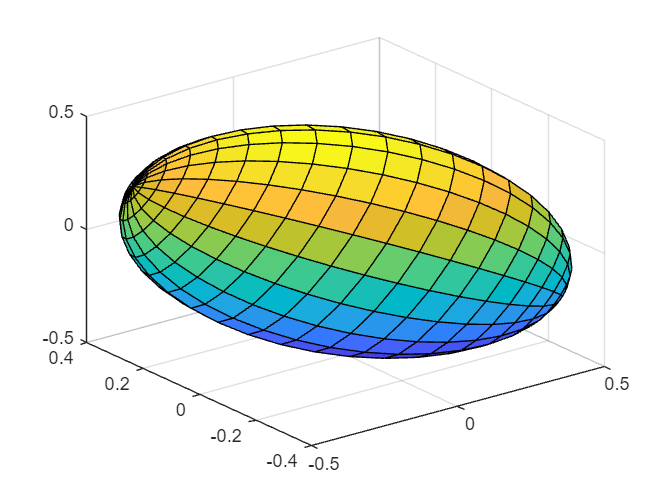

% linear ellipsoid:
[X,Y,Z] = ellipsoid(0,0,0,sqrt(V_val(1,1)),sqrt(V_val(2,2)),sqrt(V_val(3,3)));
S = surf(X,Y,Z);
rotate(S,Omega_Fw,Theta_Fw_deg);


%linear Force
JFv = Jit(4:6,:)

JFv =     3.3670   -0.8635    0.8635    0.0000   -0.0000   -3.3670
   -0.0000   -2.3529    2.3529    0.0000    0.0000    0.0000
         0   -0.0000    2.5510   -2.5510         0         0


AFv = JFv*JFv'

AFv =    24.1648    4.0637    2.2029
    4.0637   11.0727    6.0024
    2.2029    6.0024   13.0154


[AFv_vec, AFv_val] = eig(AFv)

AFv_vec =    -0.0983    0.4509   -0.8871
    0.7796   -0.5191   -0.3502
   -0.6185   -0.7261   -0.3005


AFv_val =     5.7988         0         0
         0   15.9388         0
         0         0   26.5153


%eigenvectors are a rotation matrix
Theta_Fv = acos(.5*(trace(AFv_vec)-1))

Theta_Fv = 2.8541

Theta_Fv_deg= rad2deg(Theta_Fv)

Theta_Fv_deg = 163.5294

Omega_Fv_skew = 1/(2*sin(Theta_Fv))*(AFv_vec-AFv_vec')

Omega_Fv_skew =          0   -0.5798   -0.4738
    0.5798         0    0.6628
    0.4738   -0.6628         0


Omega_Fv= so3ToVec(Omega_Fv_skew)

Omega_Fv =    -0.6628
   -0.4738
    0.5798


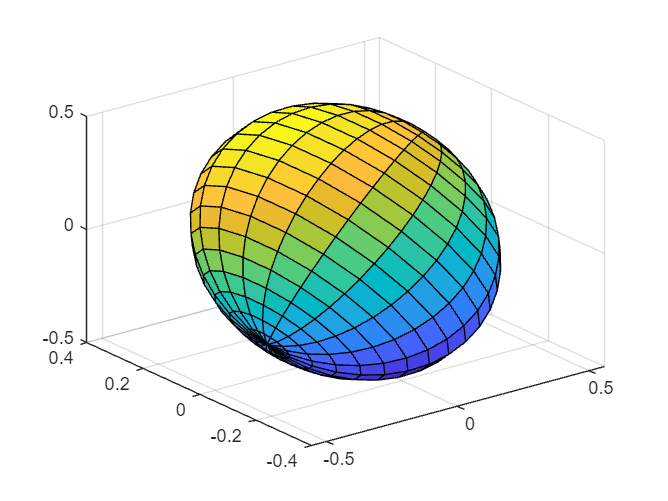

% linear ellipsoid:
[X,Y,Z] = ellipsoid(0,0,0,sqrt(V_val(1,1)),sqrt(V_val(2,2)),sqrt(V_val(3,3)));
S = surf(X,Y,Z);
rotate(S,Omega_Fv,Theta_Fv_deg);